# System 1

clc; clear;
% Symbolic Variables:
syms t alpha(t) beta(t) gamma(t)
syms h d1 d2 L L2
syms t1 t2
syms r1 r2 r3 r4
syms m1 m2 m3 m4

% L - length of gyroscope axle
% L2 - length of rotating axle
% d1 - length from A to start of big disc (B)
% d2 - length from A to start of counterweight
% t1 - thickness of disc
% t2 - thickness of counterweight
% m1 - mass of large disc
% m2 - mass of counterweight
% m3 - mass of axle
% m4 - mass of rotating axel
% r1 - radius of big disc
% r2 - radius of small disc
% r3 - radius of gyroscope axle
% r4 - radius of rotating axle

## 1) Setup Frames

% Positive rotation around z axis.
R01 = [cos(alpha) -sin(alpha) 0; sin(alpha) cos(alpha) 0; 0 0 1];
R10 = R01';

% Negative rotation around y axis.
R12 = [cos(beta) 0 -sin(beta); 0 1 0; sin(beta) 0 cos(beta)];
R21 = R12.';

% Positive rotation around x axis.
R23 = [1 0 0; 0 cos(gamma) -sin(gamma); 0 sin(gamma) cos(gamma)];
R32 = R23.';

R20 = R21 * R10;
R30 = R32 * R20;


## 2) Angular Velocities

 % not functions of time, for later

w1_1 = [0; 0; diff(alpha, t)];

w21_2 = [0; -diff(beta, t); 0];
w2_2 = w21_2 + R21*w1_1;

w32_3 = [diff(gamma, t); 0; 0];
w3_3 = w32_3 + R32*w21_2 + R32*R21*w1_1;

## 3) Position Vectors

rRC3_1 = [0; 0; L2/2]; % Base to COM of rotating axle
rRA_1 = [0; 0; -L2/2]; % A to COM of rotating axle

rACaxle_2 = [-(L/2 - d1); 0; 0]; % COM of gyroscope axle
rAD1_2 = [d1 + t1/2; 0; 0]; % A to COM of big disc
rAD2_2 = [-(d2 + t2/2); 0; 0]; % A to COM of counterweight

rAC2_2 = (m3*rACaxle_2 + m2*rAD2_2)/(m3 + m2); % combined COM of axle + counterweight

## 4) Velocity and Acceleration Vectors

rRC3_1_dot = diff(rRC3_1, t) + cross(w1_1, rRC3_1);
rRC3_1_ddot = diff(rRC3_1_dot, t) + cross(w1_1, rRC3_1_dot);

rAC2_2_dot = diff(rAC2_2, t) + cross(w2_2, rAC2_2);
rAC2_2_ddot = diff(rAC2_2_dot, t) + cross(w2_2, rAC2_2_dot);

rAD1_2_dot = diff(rAD1_2, t) + cross(w2_2, rAD1_2); 
rAD1_2_ddot = diff(rAD1_2_dot, t) + cross(w2_2, rAD1_2_dot);


## 5) Angular and Linear Momentum

%%%% Rotating Rod stuff
% Inertia tensor of axle about its own COM
xx = (1/12)*m4*(L2^2) + (1/4)*m4*(r3^2);
yy = xx;
zz = (1/2)*m4*(r4^2);
IRAxle_1 = [xx 0 0; 0 yy 0; 0 0 zz];

% derivative of linear(p) and angular(h) momentum of rotating axle in frame
% 2 about rotating axle COM
p_rotating_C3_dot = m4*rRC3_1_ddot;

h_rotating_C3 = IRAxle_1*w1_1;
h_rotating_C3_dot = diff(h_rotating_C3, t) + cross(w1_1, h_rotating_C3);


%%%% Gyroscope Rod stuff
% Inertia Tensor of counterweight about its own COM
xx = (1/2)*m2*(r2^2);
yy = (1/12)*m2*(t2^2) + (1/4)*m2*(r2^2);
zz = yy;
ID2_2 = [xx 0 0; 0 yy 0; 0 0 zz];

% Intertia tensor of just the axle about its own COM
xx = (1/2)*m3*(r3^2);
yy = (1/12)*m3*(L^2) + (1/4)*m3*(r3^2);
zz = yy;
IAxle_2 = [xx 0 0; 0 yy 0; 0 0 zz];

% Inertia tensor of counterweight about the COM of the combined gyroscope axle (C2) in frame {2}
delta_x = (rAD2_2(1) - rACaxle_2(1));
delta_y = (rAD2_2(2) - rACaxle_2(2));
delta_z = (rAD2_2(3) - rACaxle_2(3));
PAT = [delta_y^2 + delta_z^2 -delta_x*delta_y -delta_x*delta_z; -delta_x*delta_y delta_x^2 + delta_z^2 -delta_y*delta_z; -delta_x*delta_z -delta_y*delta_z delta_x^2 + delta_y^2];
ID2_C2_2 = ID2_2 + m2*PAT;
IAxle_C2_2 = IAxle_2 + ID2_C2_2;

% derivative of linear(p) and angular(h) momentum of gyroscope axle in frame
% 2 about gyroscope axle COM
p_Axle_C2_2_dot = (m2 + m3)*rAC2_2_ddot;

h_Axle_C2 = IAxle_C2_2*w2_2;
h_Axle_C2_dot = diff(h_Axle_C2, t) + cross(w2_2, h_Axle_C2);


%%%% Disc stuff
% Inertia tensor of disc about its own COM
xx = (1/2)*m1*(r1^2);
yy = (1/12)*m1*(t1^2) + (1/4)*m1*(r1^2);
zz = yy;
ID1_3 = [xx 0 0; 0 yy 0; 0 0 zz];

% derivative of linear and angualr momentum of rotating disc in frame 3
p_D1_3_dot = m1*R32*rAD1_2_ddot;
h_D1_3 = ID1_3*w3_3;
h_D1_3_dot = diff(h_D1_3, t) + cross(w3_3, h_D1_3);

## 6) FBDs

Link 3 - Rotating Disk

Fg3_0 = [0; 0; m1*9.8];
F3_3 = p_D1_3_dot - R30*Fg3_0;

MG3_3 = h_D1_3_dot;

Link 2 - Gyroscopic Axel

Fg2_0 = [0; 0; (m2+m3)*9.81];
F2_2 = p_Axle_C2_2_dot - R20*Fg2_0 + R23*F3_3;

MG2_2 = h_Axle_C2_dot + R23*MG3_3 - cross(rAC2_2, F2_2) + cross(rAD1_2, R23*F3_3);

Link 1 - Rotating Axel

Fg1_0 = [0; 0; m4*9.81];
F1_1 = p_rotating_C3_dot - R10*Fg1_0 + R12*F2_2;

MG1_2 = h_rotating_C3_dot + R12*MG2_2 - cross(rRC3_1, F1_1) + cross(rRA_1, F2_2);

## NE equations

Linear NE Rotating Disk

syms F3x F3y F3z tau_3 M3y M3z
[F3x, F3y, F3z] = solve([F3x;F3y;F3z] == F3_3, [F3x, F3y, F3z])

$$F3x = -\frac{49\,m_{1}\,\sin\left(\beta \left(t\right)\right)}{5}-m_{1}\,\left(\left(d_{1}+\frac{t_{1}}{2}\right)\,{\cos\left(\beta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}+\left(d_{1}+\frac{t_{1}}{2}\right)\,{\left(\frac{\partial }{\partial t}\beta \left(t\right)\right)}^{2}\right)$$

$$F3y = m_{1}\,\sin\left(\gamma \left(t\right)\right)\,\left(\left(d_{1}+\frac{t_{1}}{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\left(d_{1}+\frac{t_{1}}{2}\right)\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}\right)-\frac{49\,m_{1}\,\cos\left(\beta \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right)}{5}+m_{1}\,\cos\left(\gamma \left(t\right)\right)\,\left(\cos\left(\beta \left(t\right)\right)\,\left(d_{1}+\frac{t_{1}}{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)-2\,\sin\left(\beta \left(t\right)\right)\,\left(d_{1}+\frac{t_{1}}{2}\right)\,\frac{\partial }{\partial t}\beta \left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)\right)$$

$$F3z = m_{1}\,\cos\left(\gamma \left(t\right)\right)\,\left(\left(d_{1}+\frac{t_{1}}{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\left(d_{1}+\frac{t_{1}}{2}\right)\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}\right)-\frac{49\,m_{1}\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\gamma \left(t\right)\right)}{5}-m_{1}\,\sin\left(\gamma \left(t\right)\right)\,\left(\cos\left(\beta \left(t\right)\right)\,\left(d_{1}+\frac{t_{1}}{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)-2\,\sin\left(\beta \left(t\right)\right)\,\left(d_{1}+\frac{t_{1}}{2}\right)\,\frac{\partial }{\partial t}\beta \left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)\right)$$

Angular NE Rotating Disk

[tau_3, M3y, M3z] = solve([tau_3; M3y; M3z] == MG3_3, [tau_3, M3y, M3z]); 
tau_3

$$tau\_3 = \frac{m_{1}\,{r_{1}}^{2}\,\left(\sin\left(\beta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)+\frac{\partial^{2}}{\partial t^{2}}\gamma \left(t\right)+\cos\left(\beta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)\right)}{2}$$

Linear NE Gyro Axle

syms F2x F2y F2z tau_2 M2x M2z
[F2x,F2y,F2z]=solve([F2x;F2y;F2z]==F2_2, [F2x,F2y,F2z]); 


Angular NE Gyro Axle

[M2x, tau_2, M2z] = solve([M2x; tau_2; M2z] == MG2_2, [M2x, tau_2, M2z]); 
tau_2

Linear NE Rotating Axel

syms F1x F1y F1z tau_1 M1x M1y
[F1x,F1y,F1z]=solve([F1x;F1y;F1z]==F1_1, [F1x,F1y,F1z]);

Angular NE Roatation Axel

[M1x,M1y,tau_1]=solve([M1x;M1y;tau_1]==MG1_2,[M1x,M1y,tau_1]); 
tau_1

## Isolating EOM using Matrix

tau1 = 0; 
tau2 = 0; 
tau3 = 0; 
tau_1 = tau1-tau_1 ==0; 
tau_2 = tau2 -tau_2 ==0; 
tau_3 = tau3 - tau_3 == 0; 
eqns= [tau_1, tau_2, tau_3]; 

syms alpha_new beta_new gamma_new alpha_dot alpha_ddot beta_dot beta_ddot gamma_dot gamma_ddot 
old_syms = [diff(alpha, t, 2), diff(alpha, t), alpha, diff(beta,t, 2), diff(beta, t), beta, diff(gamma, t, 2), diff(gamma, t) , gamma] 

$$old\_syms(t) = \left(\begin{array}{ccccccccc} \frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right) & \frac{\partial }{\partial t}\alpha \left(t\right) & \alpha \left(t\right) & \frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right) & \frac{\partial }{\partial t}\beta \left(t\right) & \beta \left(t\right) & \frac{\partial^{2}}{\partial t^{2}}\gamma \left(t\right) & \frac{\partial }{\partial t}\gamma \left(t\right) & \gamma \left(t\right) \end{array}\right)$$

new_syms = [alpha_ddot, alpha_dot, alpha_new, beta_ddot, beta_dot, beta_new, gamma_ddot, gamma_dot, gamma_new] 

$$new\_syms = \left(\begin{array}{ccccccccc} \ddot{\alpha } & \dot{\alpha } & \alpha_{\mathrm{new}} & \ddot{\beta } & \dot{\beta } & \beta_{\mathrm{new}} & \ddot{\gamma } & \dot{\gamma } & \gamma_{\mathrm{new}} \end{array}\right)$$

eqns_new = subs(eqns, old_syms, new_syms)

% Compute simplified symbolic expression
simplifiedExpr = simplify(eqns_new)

[A ,b] = equationsToMatrix(eqns_new, [alpha_ddot, beta_ddot, gamma_ddot]) 

X_ddotNew = A\b; 
X_ddotNew = simplify(X_ddotNew); 

## Finding EOMS 

L_num =  0.48; %- length of gyroscope axle
L2_num = 0.195; %- length of rotating axle
d1_num = 0.128 %- length from A to start of big disc (B)

d1_num = 0.1280

d2_num = 0.2175;  %- length from A to start of counterweight
t1_num = 0.0221;  %- thickness of disc
t2_num = 0.0313; %- thickness of counterweight
m1_num = 1.747;  %- mass of large disc
m2_num = 0.9; % - mass of counterweight
m3_num = 0; % - mass of axle
m4_num = 0; %- mass of rotating axel
r1_num = 0.254/2;  %- radius of big disc
r2_num = 0.07/2;% - radius of counterweight
r3_num = 12.1/2/1000;  %- radius of gyroscope axle
r4_num = 12.1/2/1000; % - radius of rotating axle

sym_measurements = [L L2 d1 d2 t1 t2 m1 m2 m3 m4 r1 r2 r3 r4]; 
numerical_measurements =[L_num L2_num d1_num d2_num t1_num t2_num m1_num m2_num m3_num m4_num r1_num r2_num r3_num r4_num]; 
tau_1 = subs(tau_1, sym_measurements, numerical_measurements); 
tau_2 = subs(tau_2, sym_measurements, numerical_measurements); 
tau_3 = subs(tau_3, sym_measurements, numerical_measurements); 

## Numerical Solution

%This approach may cause S to be different order for different runs
[X_dot,S] = odeToVectorField(tau_1,tau_2, tau_3)

$$S = \left(\begin{array}{c} \alpha \\ \mathrm{Dalpha}\\ \gamma \\ {\mathrm{Dgamma}}_{\mathrm{Var}}\\ \beta \\ {\mathrm{Dbeta}}_{\mathrm{Var}} \end{array}\right)$$

eom = matlabFunction(X_dot,'Vars',{'t','Y'})

eom = function_handle with value:
    @(t,Y)[Y(2);(cos(Y(5)).*(cos(Y(3)).^2.*Y(4).*Y(6).*8.4532089e+9+sin(Y(3)).^2.*Y(4).*Y(6).*8.4532089e+9+sin(Y(5)).*Y(2).*Y(6).*4.30987059e+10-cos(Y(3)).^2.*sin(Y(5)).*Y(2).*Y(6).*1.08583270351e+11-sin(Y(3)).^2.*sin(Y(5)).*Y(2).*Y(6).*1.08583270351e+11).*-2.0)./(cos(Y(3)).^2.*cos(Y(5)).^2.*1.17036479251e+11+cos(Y(5)).^2.*sin(Y(3)).^2.*1.17036479251e+11-cos(Y(5)).^2.*4.24372059e+10+sin(Y(5)).^2.*6.615e+8);Y(4);(cos(Y(5)).*(cos(Y(5)).^2.*Y(2).*Y(6).*4.24372059e+10+sin(Y(5)).^2.*Y(2).*Y(6).*8.55359118e+10+cos(Y(3)).^2.*sin(Y(5)).*Y(4).*Y(6).*1.69064178e+10+sin(Y(3)).^2.*sin(Y(5)).*Y(4).*Y(6).*1.69064178e+10-cos(Y(3)).^2.*cos(Y(5)).^2.*Y(2).*Y(6).*1.17036479251e+11-cos(Y(3)).^2.*sin(Y(5)).^2.*Y(2).*Y(6).*2.17166540702e+11-cos(Y(5)).^2.*sin(Y(3)).^2.*Y(2).*Y(6).*1.17036479251e+11-sin(Y(3)).^2.*sin(Y(5)).^2.*Y(2).*Y(6).*2.17166540702e+11))./(cos(Y(3)).^2.*cos(Y(5)).^2.*1.17036479251e+11+cos(Y(5)).^2.*sin(Y(3)).^2.*1.17036479251e+11-cos(Y(5)).^2.*4.24372059


options = odeset('RelTol',1e-7,'AbsTol',1e-7'); % solver options
alpha0=0;
alpha_dot0=0;
beta0=0;
beta_dot0=0;
gamma0 = 0; 
gamma_dot0 = 10; 
x_init = [alpha0; alpha_dot0; beta0; beta_dot0; gamma0; gamma_dot0];   % initial condition

tspan=[0 20]; 
EOM_Solved = ode45(eom,tspan,x_init,options)

EOM_Solved = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 0.0023 0.0141 0.0281 0.0425 0.0591 0.0728 0.0841 0.0949 0.1055 0.1163 0.1274 0.1393 0.1515 0.1639 0.1767 0.1906 0.2061 0.2239 0.2422 0.2573 0.2708 0.2827 0.2928 0.3046 0.3177 0.3318 0.3470 0.3634 0.3812 0.3990 0.4161 … ] (1×1492 double)
          y: [6×1492 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


## Plotting 

%% EVAULATE THE SOLUTION
    dt = 0.03;                                  % set time step     
    t = tspan(1):dt:tspan(2);                   % creat time vector
    X = deval(EOM_Solved,t)                           % deval

X =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

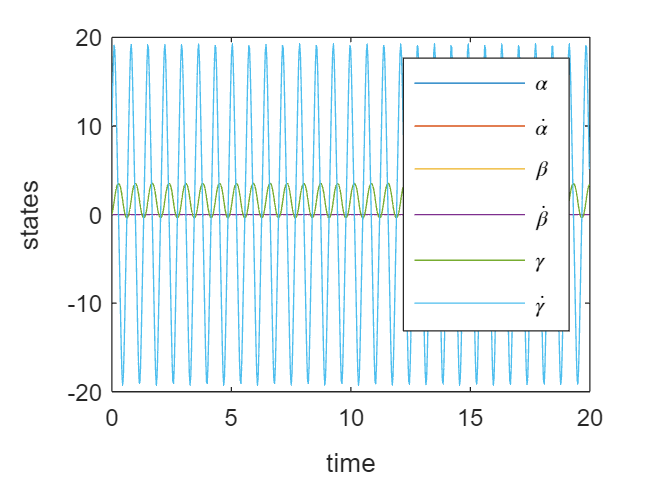



%% PLOT THE STATES
    plot(t,X)
    xlabel('time')
    ylabel('states')
    h = legend('$\alpha$','$\dot{\alpha}$','$\beta$','$\dot{\beta}$', '$\gamma$','$\dot{\gamma}$');
    set(h,'Interpreter','latex')

%{
%% ANIMATION
%% CREATE CYLINDERS
    % first entry of cylinder is the radius, (you can have functions of the
    % radius. Second entry is the number of points (the refinement). 
    % Rotating Axle
    [x1,y1,z1] = cylinder(r3_num,20)
    %Specify the height by modifying the z1 entry
    z1 = z1*L2_num;

    % Gyroscope Axle
    [x2,y2,z2] = cylinder(r3_num,20);
    %Specify the height and then the position of the second cylinder.
    z2 = z2*L_num;
    %z2 = z2-l2;
    % Gyroscope Counterweight
    [x3, y3, z3] = cylinder(r2_num, 20); 
    z3 = z3*t2_num;
    % Big Rotating Disk
    [x4, y4, z4] = cylinder(r1_num, 20); 
    z3 = z3*t1_num; 

    %% SETUP VIDEO IF REQUIRED
    if VIDEO
        fps = 1/dt;
        MyVideo = VideoWriter('two_dof_animation','MPEG-4');
        MyVideo.FrameRate = fps;
        open(MyVideo);
    end

    %% CREATE ANIMATION
    handle = figure;
    hold on % ; grid on
    for i = 1:length(t)
        cla

        theta = X(1,i);
        alpha = X(2,i);

        R1to0 = [cos(theta),-sin(theta),0;
                 sin(theta),cos(theta),0;
                 0,0,1];
        R2to1 = [cos(alpha),0,sin(alpha);
                 0 1 0;
                 -sin(alpha),0,cos(alpha)];

        [x1_rotated,y1_rotated,z1_rotated] = rotation(x1,y1,z1,R1to0);
        [x2_rotated,y2_rotated,z2_rotated] = rotation(x2,y2,z2,R1to0*R2to1);
        %Surf colours the surface of a 3 dimensional plot
        surf(x1_rotated,y1_rotated,z1_rotated,x1)%'EdgeColor','none'
        surf(x2_rotated,y2_rotated,z2_rotated,x2,'EdgeColor','none')
        axis square
        view(3)
        axis(1*[-1 1 -1 1 -1 1])
        xlabel('X')
        ylabel('Y')
        zlabel('Z')
        if VIDEO
            writeVideo(MyVideo,getframe(handle));
        else
            pause(dt)
        end
    end

    if VIDEO
    close(MyVideo)
    end

function [Xf,Yf,Zf]=rotation(Xi,Yi,Zi,R)

    I=size(Xi,1);
    J=size(Xi,2);

    Xf=zeros(I,J);
    Yf=zeros(I,J);
    Zf=zeros(I,J);

    for ii=1:I
        for jj=1:J
            vector=[Xi(ii,jj);Yi(ii,jj);Zi(ii,jj)];
            vector=R*vector;
                Xf(ii,jj)=vector(1);
                Yf(ii,jj)=vector(2);
                Zf(ii,jj)=vector(3);
        end
    end

end

%}

